## Parte de programación

El objetivo en esta sección es recuperar el texto que se encuentra distorsionado en una imagen borrosa. Como datos para trabajar el problema tenemos los siguientes:

load('DatosProy.mat')

Observamos las variables contenidas en este conjunto de datos:

whos

  Name        Size              Bytes  Class     Attributes

  A         256x256            524288  double              
  B         256x256            524288  double              
  G         256x256            524288  double              



Nótese que tenemos la imagen resumida en la matriz $G$, y otras dos matrices $A$ y $B$ tales que contienen la información del "obturador" $K$de la siguiente manera $K=A\otimes B$, en donde $\otimes \;$ representa el producto de Kronecker. Las dimensiones de $A,B\;$y $G$ son $256\times 256$, y de la matriz $K$ son ${256}^2 \times {256}^2$.

La imagen distorsionada se muestra a continuación.

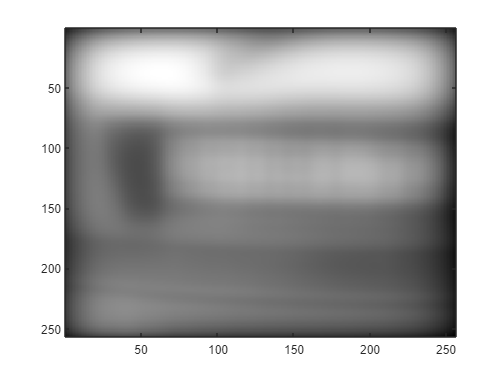

imagesc(G), colormap(gray)

Para restaurar esta imagen usamos dos métodos: Regularización de Tikhonov y Descomposición en valores singulares truncada.

Recordemos que el problema es encontrar la imagen $f$ de la ecuación $K\cdot \;f=g$ donde $K$ es el obturador y $g$ es la imagen borrosa. Considere $g$ como el vector de dimensiones ${256}^2 \times 1$ obtenido de redimensionar la matriz $G$.

%Orden de la matriz G
n = 256; 
%Redimensión de G
g =  reshape(G, n^2, 1)

g =    48.3383
   51.1216
   53.8958
   56.6217
   59.3018
   61.9131
   64.4612
   66.9284
   69.2934
   71.5343


La matriz $K$ tiene dimensiones demasiado grandes para ser manejadas por Matlab. Si calculamos el producto de Kronecker entre las matrices $A$ y $B$ nos queda una matriz con un poco más de $4\times 10^{9}$ entradas que, según Matlab, ocupa un aproximado de 32 GB; esto excede el máximo tamaño de memoria para una matriz que es de aproximadamente 7.8 GB. 

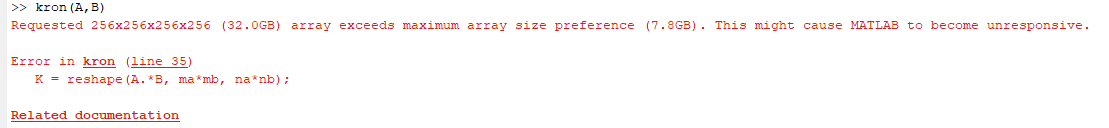

**Figura. **Error al intentar operar la matriz $K$ en Matlab.

Debido a que necesitamos la descomposición en valores singulares del obturador $K$ para aplicar los métodos, afrontamos este problema haciendo uso del siguiente teorema:

**Teorema 1. **Si $A = U_{A}\Sigma_{A} V_{A}^{T }$, $B = U_{B}\Sigma_{B} V_{B}^{T }$ y $K = A \otimes B$ entonces $K = U \Sigma V^{T}$ en donde $U = U_{A}\otimes U_{B}$, $V = V_{A}\otimes V_{B}$ y $\Sigma = \Sigma_{A}\otimes \Sigma_{B}$.

Por otra parte, para facilitar la multiplicación entre una matriz, que es igual al producto de Kronecker entre otras dos matrices más pequeñas, y un vector usamos el siguiente resultado:

**Teorema 2.** Sean $A,B\in\mathbb{R}^{n\times n}$ y $g\in\mathbb{R}^{n^2 \times 1}$. Si $G =$*reshape*$(g,n,n)$, entonces el producto $(A\otimes B)g$ puede ser calculado como

$\left(A\otimes B\right)g=$*reshape*$(BGA^{T},n^2,1)$

**Demostración (Teorema 2). **Sea $g_{i} = g((i-1)n+1 : in,1) \in R^{n\times 1}$ para $i=1,2,\ldots,n$, por ende,

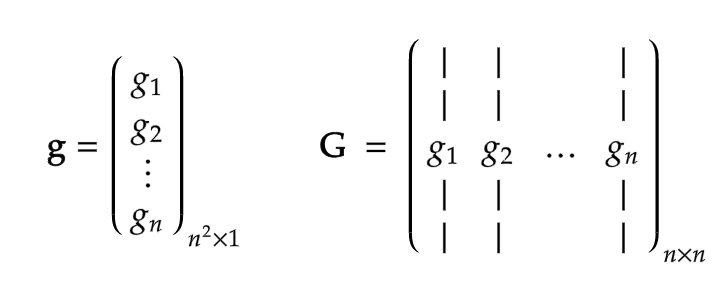

Por otra parte,

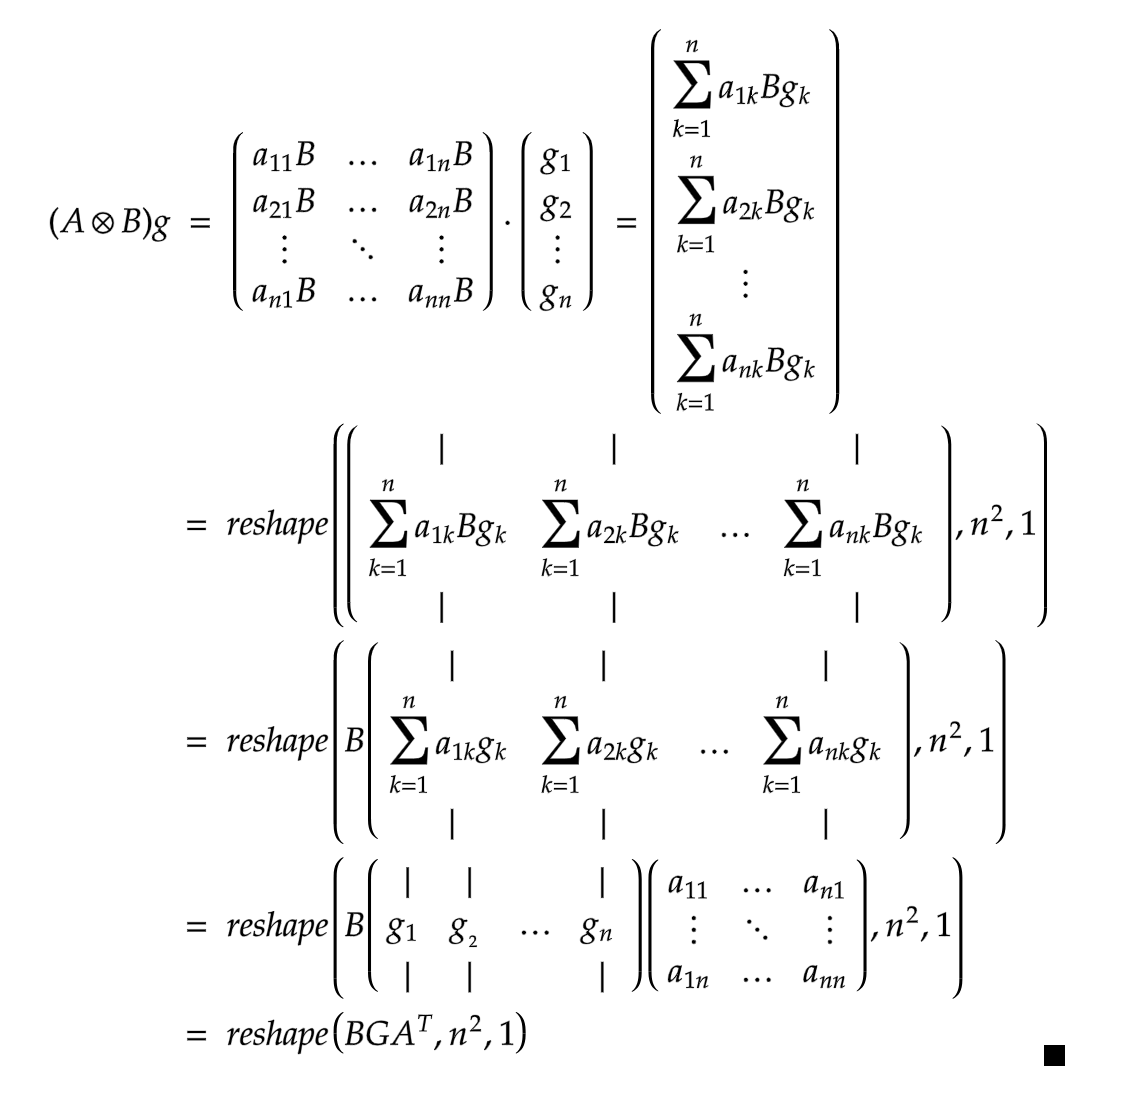

 A continuación se hace la descomposición en valores singulares de las matrices $A$ y $B$.

%Descomposición SVD de A y B
[UA, SA , VA] = svd(A);
[UB, SB , VB] = svd(B);

Analicemos los valores singulares de la matriz $K$. Por el Teorema 1 sabemos que $\Sigma = \Sigma_A \otimes \Sigma_B$, además que cada una de esta matrices es diagonal, por tanto, para calcular la matriz $\Sigma$ simplemente consideramos las entradas de la diagonal y en el código tratamos estos valores como un vector de tamaño $n^2 \times 1$ llamado *diagS. *Es sencillo notar que:


$$diag\Sigma = (1_{n\times 1} \otimes diag\Sigma_A)  \ .*\  ( diag\Sigma_B\otimes 1_{n\times 1 })$$


en donde $1_{n\times 1}$ es el vector de tamaño $n\times 1$ con todas sus componentes iguales a $1$y $.*$ representa la operación de Matlab *element wise multiplication*.

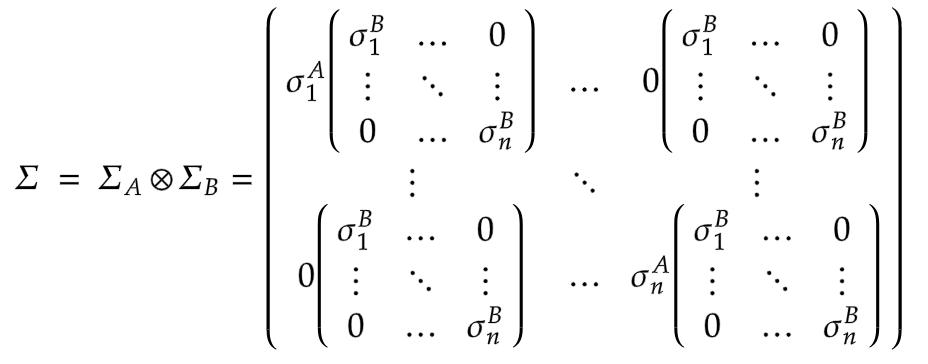 

**Figura. **Matriz de valores singulares de $K$.

%Diagonal de la matriz de valores singulares de K
diagS = kron(diag(SA),ones(n,1)).*kron(ones(n,1),diag(SB));

Para visualizar el comportamiento de los valores singulares asociados a $K$graficamos el escalamiento ($\sigma_1 = 1$) de cada valor singular.

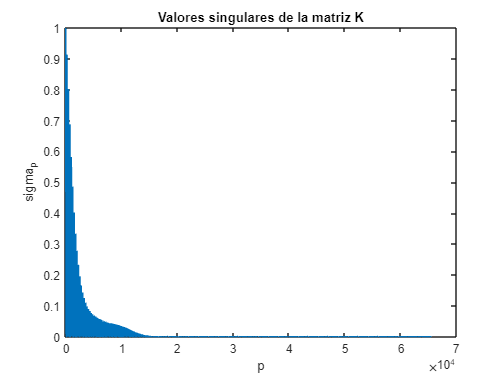

plot(diagS/diagS(1))
box on
xlabel('p')
ylabel('sigma_p')
title('Valores singulares de la matriz K')

Puede observarse que los valores singulares decaen a cero sin una separación significatica entre valores consecutivos, por lo tanto, este es un problema *mal propuesto discreto*, como se definió anteriormente.

### Regularización de Tikhonov

Sea $\alpha$ un número real positivo. Debemos encontrar un vector $f$ que esté en el conjunto solución del problema 


$$mín_{f} ||g-K f||_{2}^{2} + \alpha^2 ||f||_{2}^{2}$$


Este problema es equivalente a 


$${\textrm{mín}}_{\widehat{f} } \;||\widehat{g} -\Sigma \;\widehat{f} ||_2^2 +\alpha^2 \;||\widehat{f} ||_2^2$$


donde $\widehat{f} = V^{T} f$ y $\widehat{g} = U^{T} g$. Según lo demostrado anteriormente, se encuentra que una solución a este problema es 


$$\widehat{\underset{\min }{f}} ={\left(\Sigma^T \Sigma +\alpha^2 I\right)}^{-1} \Sigma^T \widehat{g}$$


Por ende, $f_{mín} = V \widehat{f}_{mín}$. 

Escogemos el valor de $\alpha$ manualmente, prefiriendo el valor que sirve para que la imagen sea más nítida. Probamos con $\alpha \in \{10^{-15},10^{-5},1\}$

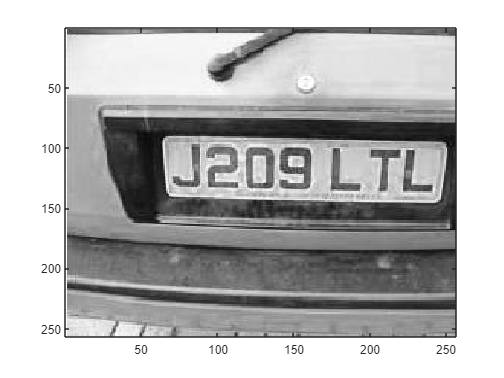

%Valor de alpha
alpha = 1E-15;
%g_shombrero = U^{T}g
ghat = reshape(UB'*G*UA,n^2,1);
%Inversa de la matriz (Sigma'Sigma + alpha^2 I)
Invalpha =1./(diagS.*diagS + alpha^2 * ones(n^2,1));

%Solución en términos de f_sombrero
fhatmin = Invalpha .* reshape(SB'*reshape(ghat,n,n)*SA,n^2,1);
%Solución en términos de f
fmin = reshape(VB*reshape(fhatmin,n,n)*VA',n^2,1);
%Redimensión de fmin
Fmin = reshape(fmin,n,n);

%Imagen obtenida
imagesc(Fmin), colormap(gray)

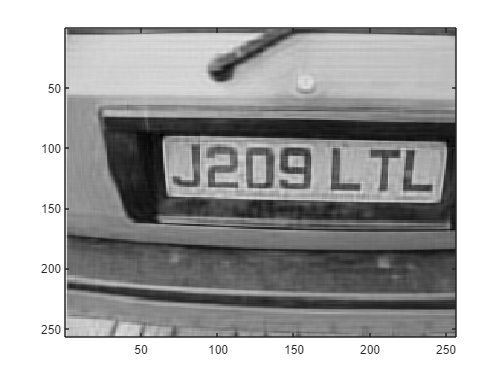

%Valor de alpha
alpha = 1E-5;
%g_shombrero = U^{T}g
ghat = reshape(UB'*G*UA,n^2,1);
%Inversa de la matriz (Sigma'Sigma + alpha^2 I)
Invalpha =1./(diagS.*diagS + alpha^2 * ones(n^2,1));

%Solución en términos de f_sombrero
fhatmin = Invalpha .* reshape(SB'*reshape(ghat,n,n)*SA,n^2,1);
%Solución en términos de f
fmin = reshape(VB*reshape(fhatmin,n,n)*VA',n^2,1);
%Redimensión de fmin
Fmin = reshape(fmin,n,n);

%Imagen obtenida
imagesc(Fmin), colormap(gray)

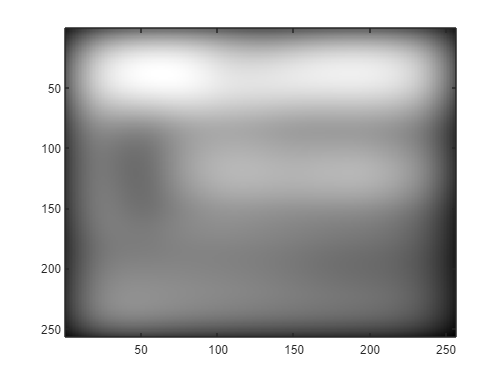

%Valor de alpha
alpha = 1;
%g_shombrero = U^{T}g
ghat = reshape(UB'*G*UA,n^2,1);
%Inversa de la matriz (Sigma'Sigma + alpha^2 I)
Invalpha =1./(diagS.*diagS + alpha^2 * ones(n^2,1));

%Solución en términos de f_sombrero
fhatmin = Invalpha .* reshape(SB'*reshape(ghat,n,n)*SA,n^2,1);
%Solución en términos de f
fmin = reshape(VB*reshape(fhatmin,n,n)*VA',n^2,1);
%Redimensión de fmin
Fmin = reshape(fmin,n,n);

%Imagen obtenida
imagesc(Fmin), colormap(gray)

Según las imágenes obtenidas vemos que mientras más pequeño es el valor de $\alpha$ obtenemos una imagen más nitida.

### Descomposición en valores singulares truncada

Para hallar la solución por medio de este método, tomamos un valor $p$ en el conjunto $\{1,\ldots,n^2\}$ y hacemos la sumatoria $f_{ls}  =\sum_{i=1}^{p}\frac{u_i v_{i}^{T}}{\sigma_i} g$. A continuación tomamos $p=15000$.

% Valor en donde se trunca la sumatoria
p = 15000;

%Inicialización: Vector solución 
fls = zeros(n^2,1);
%Inicialización: Vector canónico i-ésimo
% en R^{n^2}
ei = zeros(n^2,1);
%Inicialización: Columna i-ésima de U 
Up = zeros(n^2,1);
%Inicialización: Columna i-ésima de V 
Vp = zeros(n^2,1);

%Sumatoria
for i = 1:p
    ei = zeros(n^2,1);
    ei(i) = 1;
    Ep = reshape(ei,n,n);
    Up = reshape(UB*Ep*UA',n^2,1);
    Vp = reshape(VB*Ep*VA',n^2,1);
    fls = fls + (1/diagS(i))*(Up'*g)*Vp;
end
% Redimensión de la imagen
Fls = reshape(fls,n,n);

El truncamiento de la sumatoria hasta $p=15000$ arroja como resultado la siguiente imagen.

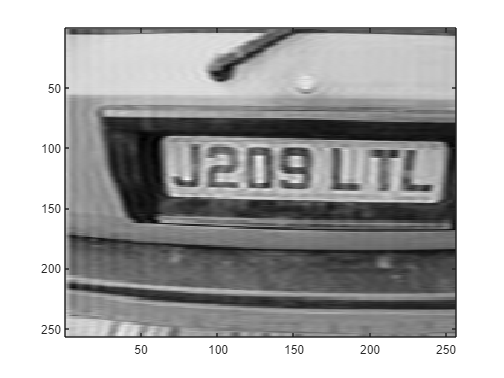

imagesc(Fls), colormap(gray)

Una manera más eficiente en términos de tiempo pero equivalente en precisión es la siguiente: Sabemos que $f = V \Sigma^{+}U^{T}g$, de esto se sigue,

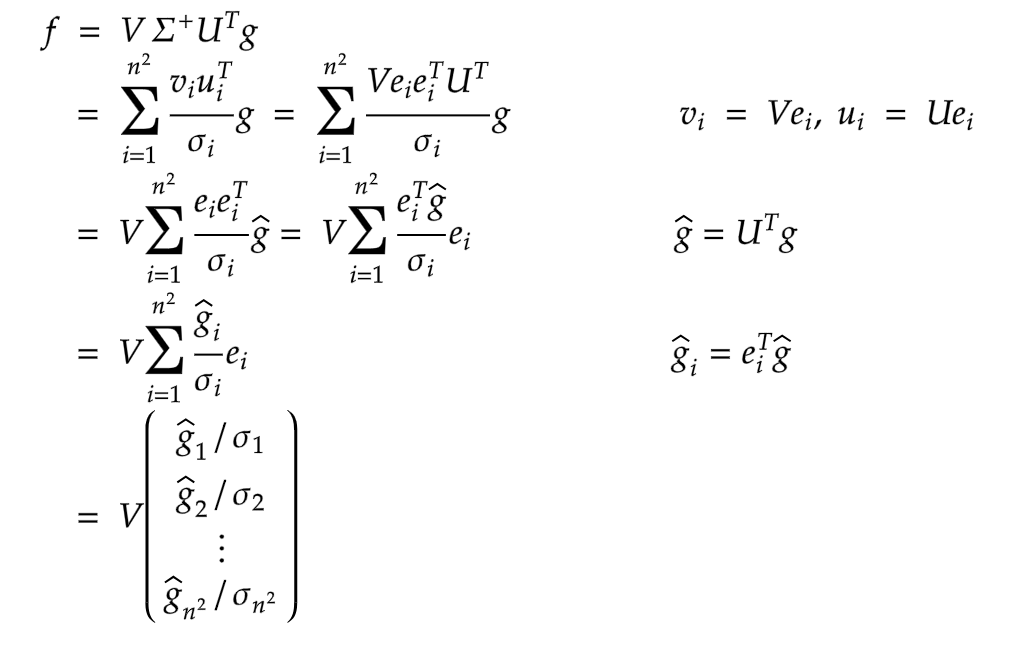

Para hacer el truncamiento de la sumatoria hasta un valor $p$ hacemos el siguiente cálculo basados en lo anterior,

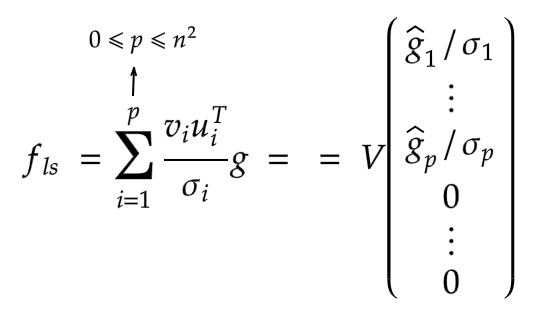

El vector que aparece en el cálculo de $f_{ls}$ en la anterior ecuación se puede calcular en Matlab como 


$$\widehat{g}\ .* \ [1\ ./\ diagS(1:p,1) ;   zeros(n^2-p,1)]$$


donde $.*$y $./$ representan operaciones *element wise.*

Nótese que este proceso es mucho más sencillo de manejar dado que no es necesario involucrar una estructura repetitiva (*for*) en el código.

Para escoger el valor de $p$ indagamos sobre el porcentaje que representa la sumatoria truncada hasta $p$ sobre la suma de todos los valores singulares de la matriz $K$. 

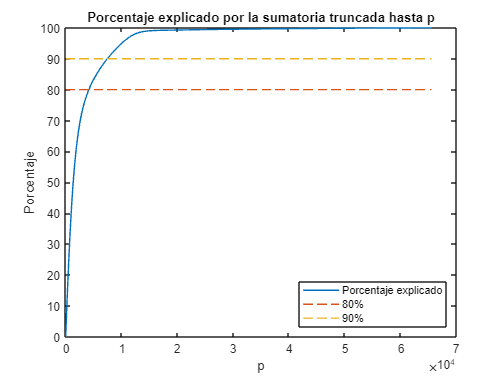

step = 0:n:n^2;
sizestep = n+1;
Porcentaje_explicado = zeros(sizestep,1);
for i= 1:sizestep
    Porcentaje_explicado(i) = 100*sum(diagS(1:step(i)))/sum(diagS);
end

plot(step, Porcentaje_explicado, step, 80+0*step,'--',step, 90+0*step,'--')
box on
xlabel('p')
ylabel('Porcentaje')
title('Porcentaje explicado por la sumatoria truncada hasta p')
[a,b]=legend('Porcentaje explicado','80%','90%','Location','southeast');

set(b(1),'Color','b')
set(b(2),'Color','r')
set(b(3),'Color','k')

Como se puede evidenciar

- alrededor de $p=4200$ se alcanza el $80\%$ de la suma total,

- en aproximadamente $p=7500$ se alcanza el $90\%$ de la suma total, y

- si $p$ es mayor o igual a $15000$ se supera el $99\%$ del valor de la sumatoria.

% Porcentaje para p=4200
disp(100*sum(diagS(1:4200))/sum(diagS))

   80.8603



% Porcentaje para p=7500
disp(100*sum(diagS(1:7500))/sum(diagS))

   90.4838



% Porcentaje para p=15000
disp(100*sum(diagS(1:15000))/sum(diagS))

   99.0726



Para cada uno de estos valores, graficamos la imagen obtenida

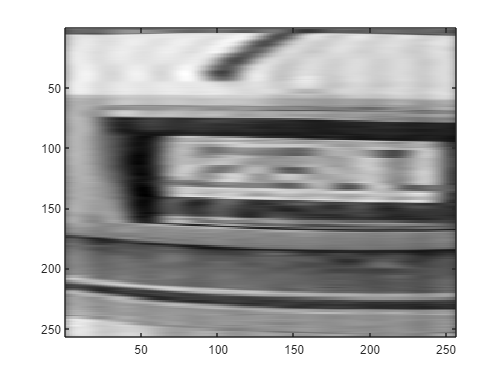

%Con un 80% de porcentaje explicado
p = 4200;

% Vector truncado
wp = ghat.* [1./diagS(1:p,1) ; zeros(n^2-p,1)]; 
% Solución de mínimos cuadrados
fls0 = reshape(VB*reshape(wp,n,n)*VA',n^2,1);
%Redimensión de fls0
Fls0 = reshape(fls0,n,n);

%Imagen obtenida
imagesc(Fls0), colormap(gray)

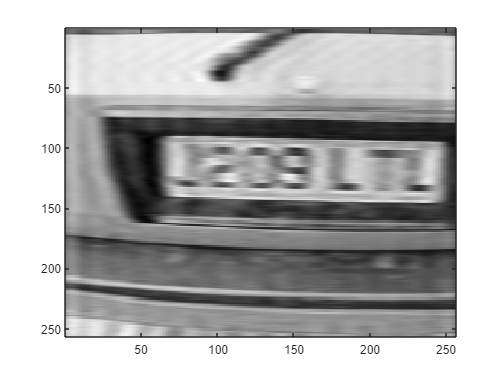

%Con un 90% de porcentaje explicado
p = 7500;

% Vector truncado
wp = ghat.* [1./diagS(1:p,1) ; zeros(n^2-p,1)]; 
% Solución de mínimos cuadrados
fls0 = reshape(VB*reshape(wp,n,n)*VA',n^2,1);
%Redimensión de fls0
Fls0 = reshape(fls0,n,n);

%Imagen obtenida
imagesc(Fls0), colormap(gray)

%Con un 99% de porcentaje explicado
p = 15000;

% Vector truncado
wp = ghat.* [1./diagS(1:p,1) ; zeros(n^2-p,1)]; 
% Solución de mínimos cuadrados
fls0 = reshape(VB*reshape(wp,n,n)*VA',n^2,1);
%Redimensión de fls0
Fls0 = reshape(fls0,n,n);

%Imagen obtenida
imagesc(Fls0), colormap(gray)

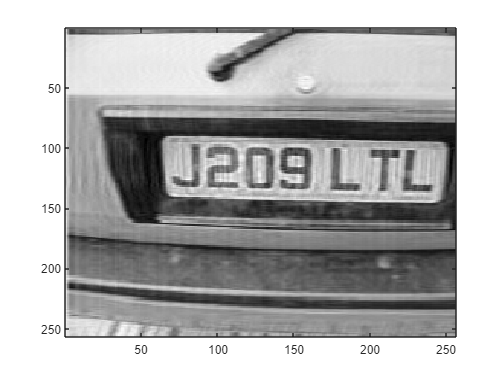

%Con un 99.45% de porcentaje explicado
p = 25000;

% Vector truncado
wp = ghat.* [1./diagS(1:p,1) ; zeros(n^2-p,1)]; 
% Solución de mínimos cuadrados
fls0 = reshape(VB*reshape(wp,n,n)*VA',n^2,1);
%Redimensión de fls0
Fls0 = reshape(fls0,n,n);

%Imagen obtenida
imagesc(Fls0), colormap(gray)

Nótese que mientras se aumenta el valor de truncamiento $p$ la imagen obtenida es más nítida. Cabe también destacar que entre $p=15000$ y $p=25000$ no hay mucha diferencia del resultado.

%Cambio porcentual de la solución cuando esta p=15000 y pasa a p=25000
100*norm(reshape(VB*reshape(ghat.* [1./diagS(1:25000,1) ; zeros(n^2-25000,1)],n,n)*VA',n^2,1)-reshape(VB*reshape(ghat.* [1./diagS(1:15000,1) ; zeros(n^2-15000,1)],n,n)*VA',n^2,1))/norm(reshape(VB*reshape(ghat.* [1./diagS(1:15000,1) ; zeros(n^2-15000,1)],n,n)*VA',n^2,1))

ans = 4.0802

Para finalizar, por ambos métodos concluimos que el texto en la imagen es **J209 LTL**. A simple vista el método de regularización arroja una imagen 'mejor' en términos de nitidez en contraste con el método SVD truncado. A lo largo de esta parte de programación se tomaron los valores de $\alpha$ y de $p$ de manera manual, por ende, para hacer una comparación completamente justificada entre ambos métodos es necesario tener un critero preciso sobre qué tan 'buena' es la imagen obtenida dependiendo de la sensibilidad de los parámetros de cada método.